## **Finite Element Method**

clc; 
clear;
syms x f(x) u_e(x) h

a=1

a = 1

c =3*x

$$c = 3\,x$$


% No of elements
e = 6;
% No of Nodal points
n =e+1;

f(x) = 4*x^2 - 2*x -4;

deqn = a*diff(u_e,x,2)+c*u_e == f;

Value1 = 0;
Value2 = 1;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
%ic2 = d_ue(1) == Value2;

ic2=u_e(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;

% domain of X
x0 = 0;
xn = 1;
% Element length
h_num = (xn - x0) / e;

% At nodel point the value of x
X = (x0:h_num:xn)';
f_x = sym(zeros(n, 1));

% Calculate f(x) for each x value symbolically and store in the vector
for i = 1:n
    f_x(i) = subs(f, x, X(i));
end
%disp(f_x);

% Define Shape Functions
phi_1 = 1 - x/h;
phi_2 = x/h;

phi_e = [phi_1; phi_2];

% Local stiffness matrix
KNM_local = zeros(2, 2, 'sym');
CNM_local = zeros(2, 2, 'sym');

for N = 1:2
    for M = 1:2
        % Integrate to get the local stiffness matrix
        KNM_local(N, M) = int(a * diff(phi_e(N), x) * diff(phi_e(M), x) - c * phi_e(N) * phi_e(M), x, 0, h);
        CNM_local(N, M) = int(-1* phi_e(N) * phi_e(M), x, 0, h);
    end
end

% Display the local stiffness matrix
disp('Local Stiffness Matrix some element e:');

Local Stiffness Matrix some element e:


disp(KNM_local);

$$\left(\begin{array}{cc} \frac{1}{h}-\frac{h^{2}}{4} & -\frac{1}{h}-\frac{h^{2}}{4}\\ -\frac{1}{h}-\frac{h^{2}}{4} & \frac{1}{h}-\frac{3\,h^{2}}{4} \end{array}\right)$$

disp('Local C_NM Matrix some element e:');

Local C_NM Matrix some element e:


disp(CNM_local);

$$\left(\begin{array}{cc} -\frac{h}{3} & -\frac{h}{6}\\ -\frac{h}{6} & -\frac{h}{3} \end{array}\right)$$



% Substitute values into the local  matrices
KNM_local_sub = subs(KNM_local, h, h_num);
CNM_local_sub = subs(CNM_local, h, h_num);

% Display the substituted local stiffness matrix
disp('Substituted values of a c and h in Local Stiffness Matrix:');

Substituted values of a c and h in Local Stiffness Matrix:


disp(KNM_local_sub);

$$\left(\begin{array}{cc} \frac{863}{144} & -\frac{865}{144}\\ -\frac{865}{144} & \frac{287}{48} \end{array}\right)$$

disp('Substituted value h in Local C_NM Matrix:');

Substituted value h in Local C_NM Matrix:


disp(CNM_local_sub);

$$\left(\begin{array}{cc} -\frac{1}{18} & -\frac{1}{36}\\ -\frac{1}{36} & -\frac{1}{18} \end{array}\right)$$


% Initialize global stiffness matrix
global_matrix_size = n; % each element has 2 nodal points
K_global = zeros(global_matrix_size);
C_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:n-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + 1;
    K_global(start_index:end_index, start_index:end_index) = K_global(start_index:end_index, start_index:end_index) + KNM_local_sub;
    C_global(start_index:end_index, start_index:end_index) = C_global(start_index:end_index, start_index:end_index) + CNM_local_sub;
end

% Display global stiffness matrix
disp('Global Stiffness Matrix:')

Global Stiffness Matrix:


disp(K_global);

    5.9931   -6.0069         0         0         0         0         0
   -6.0069   11.9722   -6.0069         0         0         0         0
         0   -6.0069   11.9722   -6.0069         0         0         0
         0         0   -6.0069   11.9722   -6.0069         0         0
         0         0         0   -6.0069   11.9722   -6.0069         0
         0         0         0         0   -6.0069   11.9722   -6.0069
         0         0         0         0         0   -6.0069    5.9792



disp('Global C Matrix:')

Global C Matrix:


disp(C_global);

   -0.0556   -0.0278         0         0         0         0         0
   -0.0278   -0.1111   -0.0278         0         0         0         0
         0   -0.0278   -0.1111   -0.0278         0         0         0
         0         0   -0.0278   -0.1111   -0.0278         0         0
         0         0         0   -0.0278   -0.1111   -0.0278         0
         0         0         0         0   -0.0278   -0.1111   -0.0278
         0         0         0         0         0   -0.0278   -0.0556




%K_global_inverse=InverseTDMA(K_global)

CNM = C_global*f_x;

du_dx = -3;

% Dirichlet Boundary Conditions

K_global_D_bc = K_global;
g_x_D_bc = sym(zeros(n, 1));
GNM_D_bc= a*g_x_D_bc*du_dx;
RHS_D_bc = GNM_D_bc+CNM;

% Boundary Conditions1
u0 = Value1;
K_global_D_bc(1,:)= [1,zeros(1, n-1)];  %u0 = 0
RHS_D_bc(1) = u0;  % RHS of equation

% Boundary Conditions2
un = Value2;
K_global_D_bc(end,:)= [zeros(1, n-1), 1];  %un=-1
RHS_D_bc(end) = un;  % RHS of equation



%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc\RHS_D_bc);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point       u   
    ___________    _______

            0            0
      0.16667      0.45514
      0.33333      0.79101
          0.5       1.0053
      0.66667       1.1026
      0.83333       1.0947
            1            1



disp("-------------------------------------------------------------")

-------------------------------------------------------------


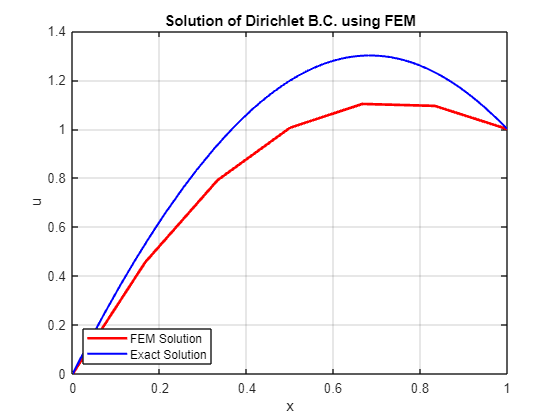

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [0 1], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;